# Square Input (Deterministic)

clear;
clc;

Loading 2nd run of case30

load('30_1.mat');

Input values

y1_30_1=scope.signals(1).values; 

y1_30_1=y1_30_1.';
x1_30_1=tout;
x1_30_1=x1_30_1.';

figure
plot(x1_30_1,y1_30_1)
hold on


Response values

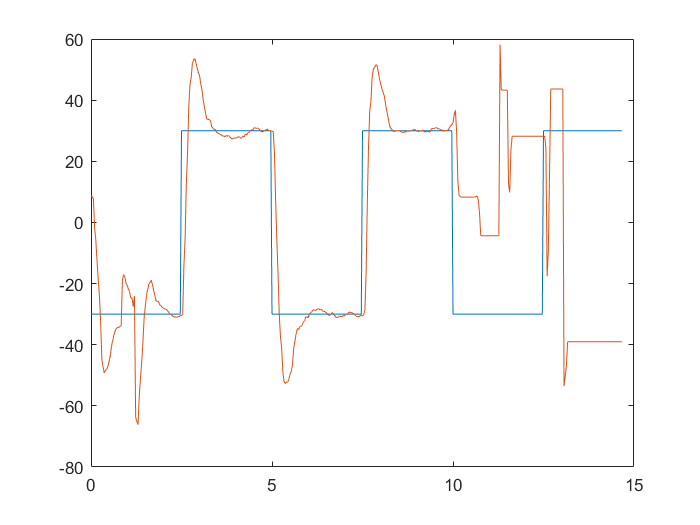

y2_30_1=scope.signals(2).values; 

y3_30_1=squeeze(y2_30_1);
y3_30_1=y3_30_1.';
constref=80;
y3_30_1=y3_30_1-constref;

plot(x1_30_1,y3_30_1);
hold off

Chosing points (step4)

case30_1_y=y3_30_1(226:254);

Forcing first point as y=0

const30_1=y3_30_1(226);
case30_1_y=case30_1_y-const30_1;
case30_1_t=x1_30_1(1:29);

case30_1_y(2)=-3,0219;

case30_1_y =          0   -3.0000    1.9776   14.2418   37.3131   55.5276   67.2059   70.3565   78.2414   80.8375   81.3526   82.1495   82.0620   80.0716   77.8345   75.9710   74.5724   73.1885   72.1052   69.7234   67.3004   65.4201   63.1677   61.6759   61.2739   60.6325   60.3297   60.5259   60.5391


% case30_1_y(2)=[];

figure
plot(case30_1_t,case30_1_y);
hold on

Picking points from the reference for comparison

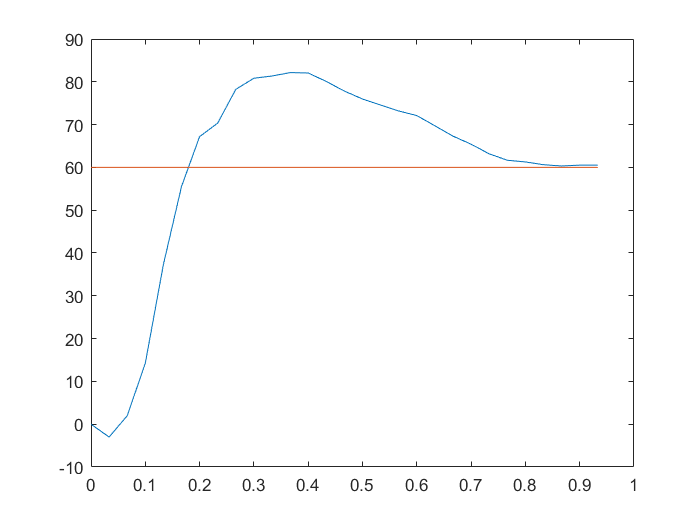

case30_1_yref=y1_30_1(226:254);
const30_1_yref=y1_30_1(226);
case30_1_yref=case30_1_yref+const30_1_yref;

plot(case30_1_t,case30_1_yref);
hold off

Tratamento de dados para Deconv

case30_1_yref_deconv=y1_30_1(226:254); %U(0)->U(N-1)
const30_1_yref_deconv=y1_30_1(226);
U=case30_1_yref_deconv+const30_1_yref_deconv;
Udeconv_30_1=U';

case30_1_y_deconv=y3_30_1(227:254); %Y(1)->Y(N)(um step a tráz de U)
const30_1_deconv=y3_30_1(226);
Y=case30_1_y_deconv-const30_1_deconv;
Ydeconv_30_1=Y';
Ydeconv_30_1(1)=0;

Ydeconv_30_1(29)=0;
Ydeconv_30_1_2 = circshift(Ydeconv_30_1,1);
Ydeconv_30_1_2(2)=-1;

Ts=1/30;

Performing Deconvolution 

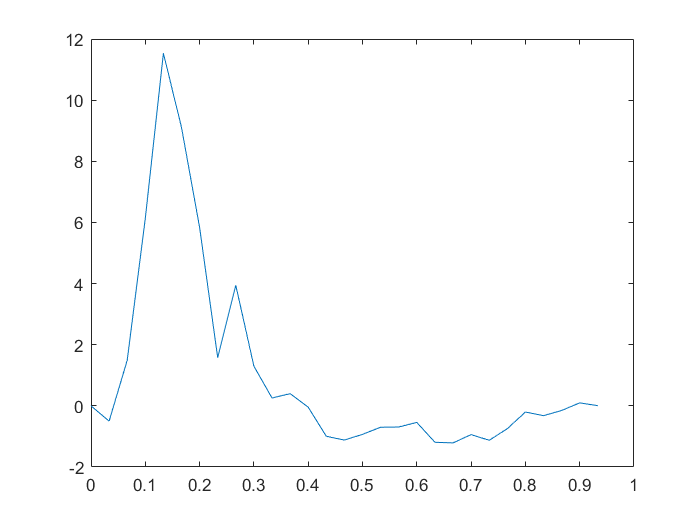

g_30_1 = Deconv(Udeconv_30_1,Ydeconv_30_1_2,Ts);

T_30_1=x1_30_1(1:29);
 
figure
% plot(T_30_1,Ydeconv_30_1_2);
% hold on

plot(T_30_1,g_30_1);
hold off

Obtaining G(z) and G(s)

n=3;
inputgz=zeros(7,1); %2n+1=7, 3rd order system
k=1;
for i = 1:2:13
    input_gz(k,1)=g_30_1(i);
    k=k+1;
end
g=input_gz;
Ts=1/15; %re-sample

Gz=ir2dtf(g,n,Ts)


Gz =
 
      1.489 z^2 + 11.18 z + 2.719
  ------------------------------------
  z^3 - 0.2389 z^2 - 0.2444 z + 0.1831
 
Sample time: 0.066667 seconds
Discrete-time transfer function.



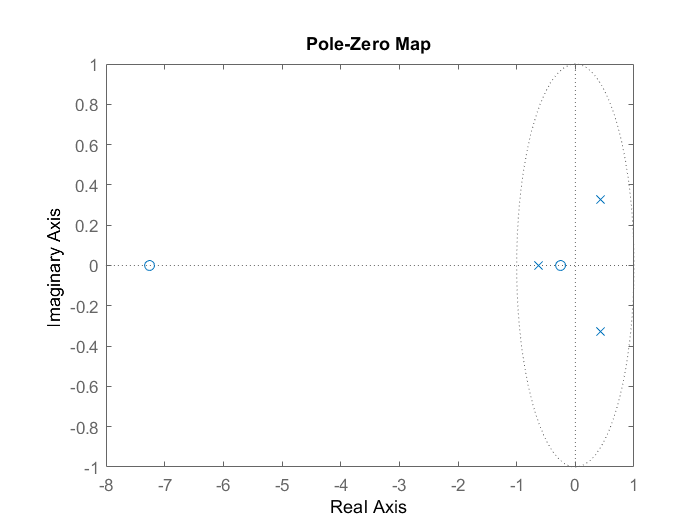

pzmap(Gz)

Gd2d=d2d(Gz,1/30)


Gd2d =
 
    -1.137 z^3 + 4.212 z^2 + 1.056 z + 1.108
  ---------------------------------------------
  z^4 - 1.395 z^3 + 1.165 z^2 - 0.87 z + 0.3379
 
Sample time: 0.033333 seconds
Discrete-time transfer function.



Gs=d2c(Gd2d)


Gs =
 
   -63.37 s^3 - 881.5 s^2 - 1.332e05 s + 8.968e06
  -------------------------------------------------
  s^4 + 32.55 s^3 + 2711 s^2 + 4.43e04 s + 4.078e05
 
Continuous-time transfer function.



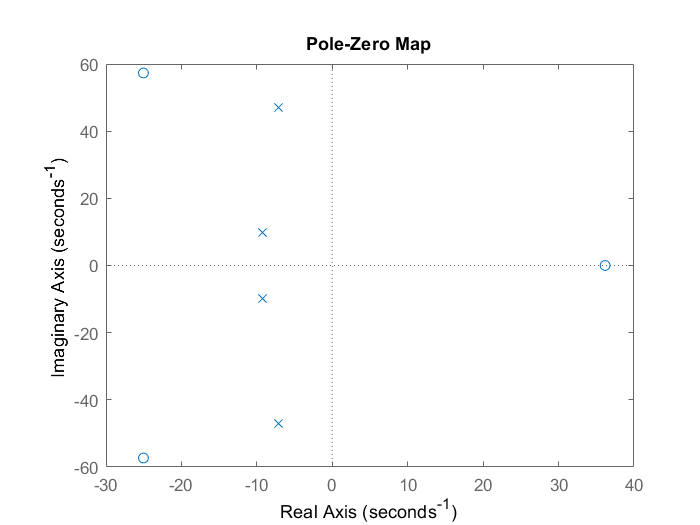

figure
pzmap(Gs)

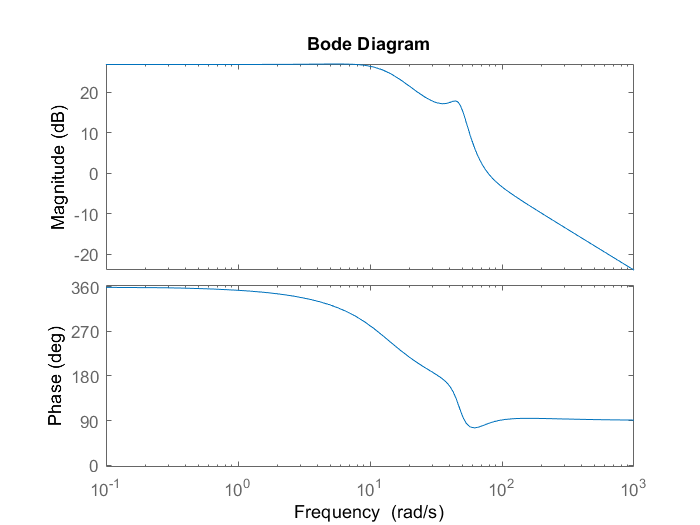

figure
bode(Gs)


Gs_m=minreal(Gs,0.1) %pole-zero cancelation (reducing order)


Gs_m =
 
   -63.37 s^3 - 881.5 s^2 - 1.332e05 s + 8.968e06
  -------------------------------------------------
  s^4 + 32.55 s^3 + 2711 s^2 + 4.43e04 s + 4.078e05
 
Continuous-time transfer function.




figure
pzmap(Gs_m)

figure
bode(Gs_m)  


[Gs_30_final]=modelreducerapp30(Gs_m);
Gs_30_final=Gs_30_final/30%putting gain back to normal


Gs_30_final =
 
      -50.24 s + 4282
  -----------------------
  30 s^2 + 551.6 s + 5387
 
Continuous-time transfer function.



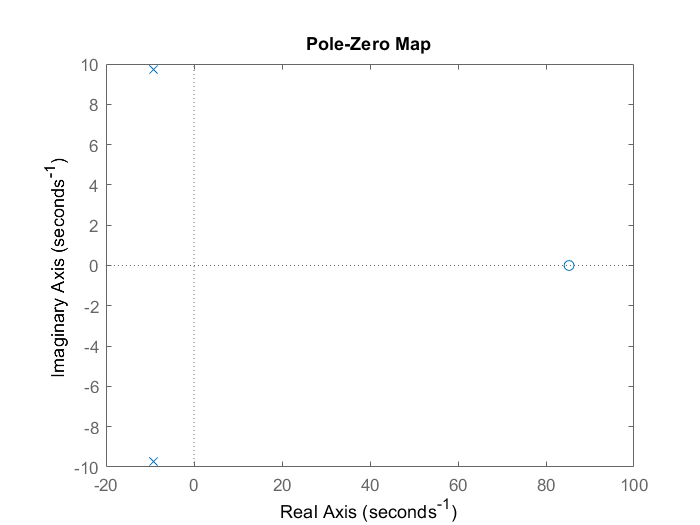


figure
pzmap(Gs_30_final)

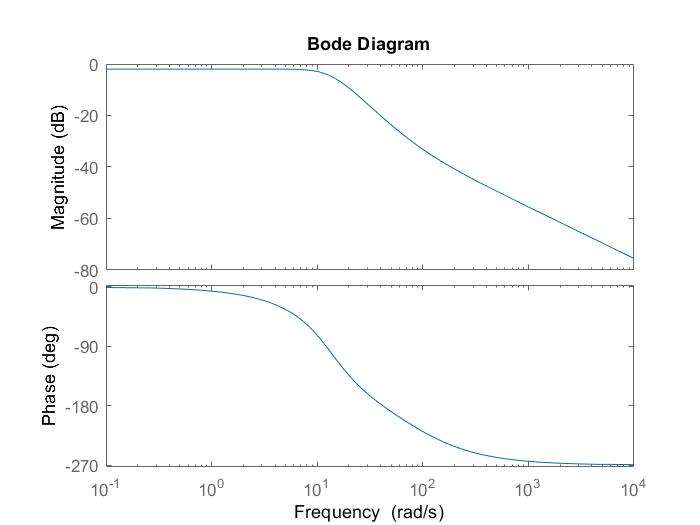

figure
h=bodeplot(Gs_30_final);
opt = getoptions(h);  %phase offset correction
opt.PhaseMatching = 'on'; 
opt.PhaseMatchingFreq = 0.1; 
opt.PhaseMatchingValue = 0;
setoptions(h,opt); %update phase plot

Calculating Fourier Transform

g_30_1_cut=g_30_1(1:11); %until deconv impulse response returns to zero
[PHASE,GAIN,W]=fourier(g_30_1_cut);
PHASEdegree=unwrap(PHASE)*180/pi;

Cutting frequencies higher than 30rad/s

W_cut=W(1:38); 
GAIN_cut=GAIN(1:38);
PHASE_cut=PHASEdegree(1:38);

Levy Method

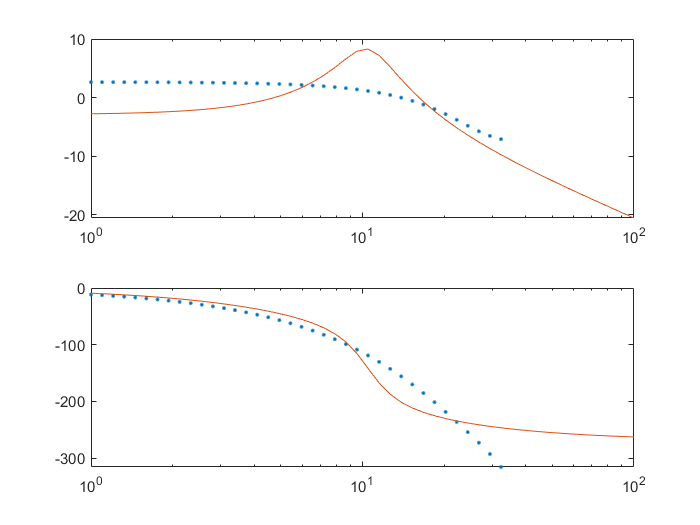

Q.num=[1 0];
Q.den=[2 1 0];
[G_levy, J, handle] = levy (W_cut, GAIN_cut, PHASE_cut, Q, 0);

Gs_levy=tf(G_levy.num,G_levy.den)


Gs_levy =
 
      -0.08419 s + 0.7147
  ----------------------------
  0.009141 s^2 + 0.04178 s + 1
 
Continuous-time transfer function.



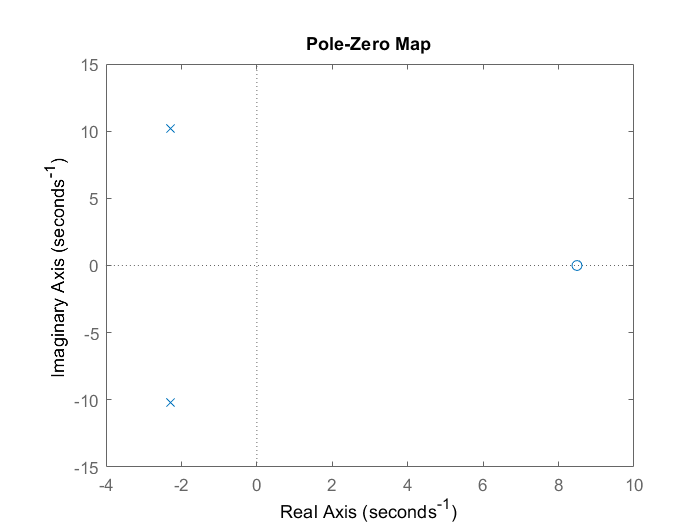


figure
pzmap(Gs_levy)

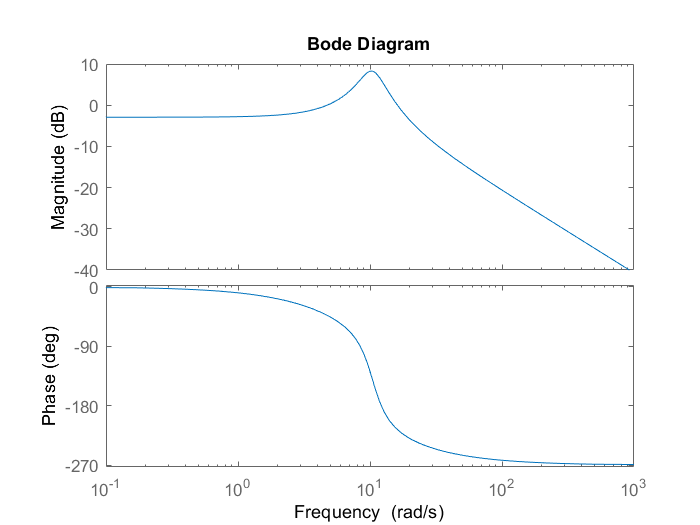

figure

h=bodeplot(Gs_levy);
opt = getoptions(h);  %phase offset correction
opt.PhaseMatching = 'on'; 
opt.PhaseMatchingFreq = 0.1; 
opt.PhaseMatchingValue = 0;
setoptions(h,opt); %update phase plot    

Comparing bode diagrams

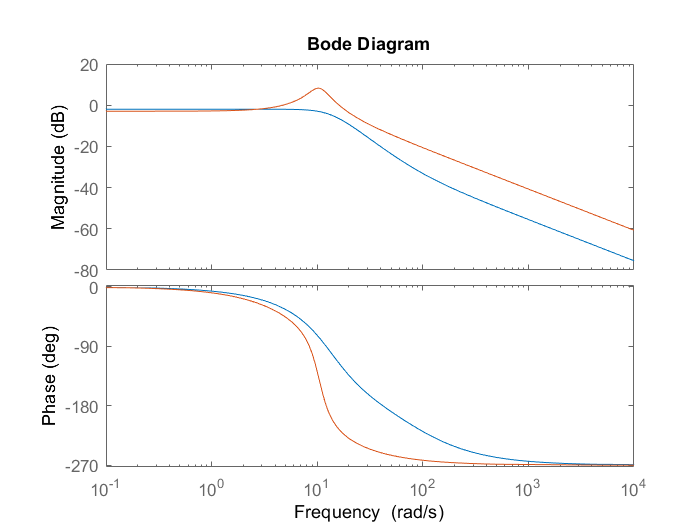

figure
h=bodeplot(Gs_30_final);
opt = getoptions(h);  %phase offset correction
opt.PhaseMatching = 'on'; 
opt.PhaseMatchingFreq = 0.1; 
opt.PhaseMatchingValue = 0;
setoptions(h,opt); %update phase plot
hold on

h=bodeplot(Gs_levy);
opt = getoptions(h);  %phase offset correction
opt.PhaseMatching = 'on'; 
opt.PhaseMatchingFreq = 0.1; 
opt.PhaseMatchingValue = 0;
setoptions(h,opt); %update phase plot  
hold off

# Sinusoidal Input Comparison

gain=[0.9961 2.5484 4.2314 -2.7888 -4.2465];
phase=[-0.7100 -5.2187 -46.0971 -131.5551 -146.6613];
w=[0.7363 1.4726 5.8905 17.615 23.5619];

Comparing data

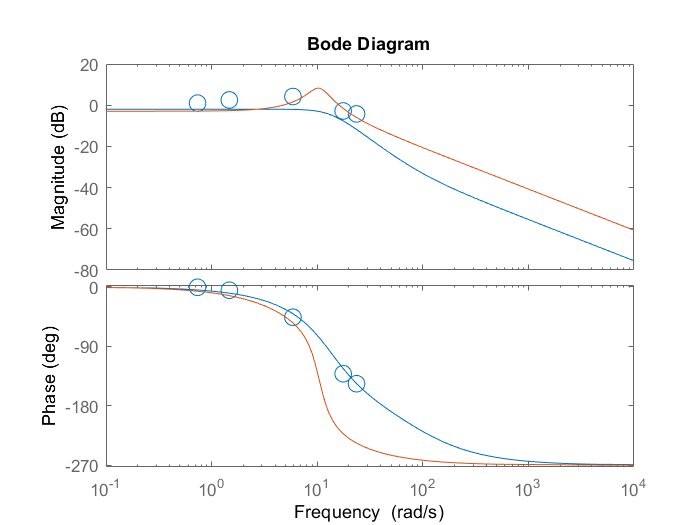

figure
semilogx(w,gain,'o','MarkerSize',10)
hold on

h=bodeplot(Gs_30_final);
opt = getoptions(h);  %phase offset correction
opt.PhaseMatching = 'on'; 
opt.PhaseMatchingFreq = 0.1; 
opt.PhaseMatchingValue = 0;
setoptions(h,opt); %update phase plot
hold on

semilogx(w,phase,'o','MarkerSize',10)
hold on

h=bodeplot(Gs_levy);
opt = getoptions(h);  %phase offset correction
opt.PhaseMatching = 'on'; 
opt.PhaseMatchingFreq = 0.1; 
opt.PhaseMatchingValue = 0;
setoptions(h,opt); %update phase plot
hold off